# Exercício 5

clear all;
clc;
close all;



## Análise de fourier

syms n t

T0= 1                          % período

T0 = 1

f0 = 1/T0

f0 = 1

w0 = 2*pi*f0

w0 = 6.2832


gt = exp(-t)

$$gt = {\mathrm{e}}^{-t}$$

g = @(t) (exp(-t));
gn = @(n) exp(-(j)*n*w0*t);

N = 100;
n=[-N:1:N];
tempoN = [0:1/(N*100):T0];

cn = int(gt*gn,t,0,T0)/T0;

resc = eval(cn)

resc =    0.0000 + 0.0010i   0.0000 + 0.0010i   0.0000 + 0.0010i   0.0000 + 0.0010i   0.0000 + 0.0010i   0.0000 + 0.0011i   0.0000 + 0.0011i   0.0000 + 0.0011i   0.0000 + 0.0011i   0.0000 + 0.0011i   0.0000 + 0.0011i   0.0000 + 0.0011i   0.0000 + 0.0011i   0.0000 + 0.0012i   0.0000 + 0.0012i   0.0000 + 0.0012i   0.0000 + 0.0012i   0.0000 + 0.0012i   0.0000 + 0.0012i   0.0000 + 0.0012i   0.0000 + 0.0013i   0.0000 + 0.0013i   0.0000 + 0.0013i   0.0000 + 0.0013i   0.0000 + 0.0013i   0.0000 + 0.0013i   0.0000 + 0.0014i   0.0000 + 0.0014i   0.0000 + 0.0014i   0.0000 + 0.0014i   0.0000 + 0.0014i   0.0000 + 0.0015i   0.0000 + 0.0015i   0.0000 + 0.0015i   0.0000 + 0.0015i   0.0000 + 0.0015i   0.0000 + 0.0016i   0.0000 + 0.0016i   0.0000 + 0.0016i   0.0000 + 0.0016i   0.0000 + 0.0017i   0.0000 + 0.0017i   0.0000 + 0.0017i   0.0000 + 0.0018i   0.0000 + 0.0018i   0.0000 + 0.0018i   0.0000 + 0.0019i   0.0000 + 0.0019i   0.0000 + 0.0019i   0.0000 + 0.0020i


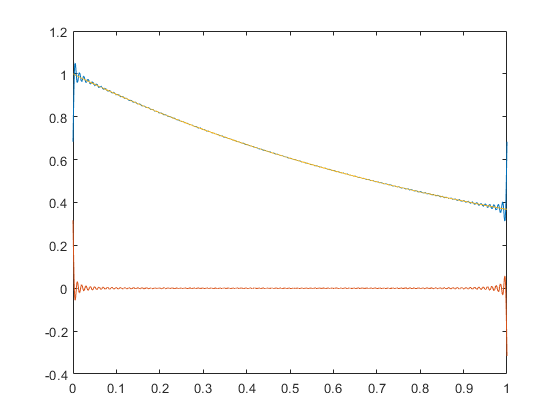



pn = 0;

for k=1:2*N+1
 pn = pn + resc(k)*exp(j*n(k)*w0*tempoN);
end

rnt = g(tempoN) - pn;

%%help cumsum



figure(1)

plot(tempoN,pn ,tempoN,rnt ,tempoN,g(tempoN))